# Semana 1 - Laboratorio

## Ejemplo 3

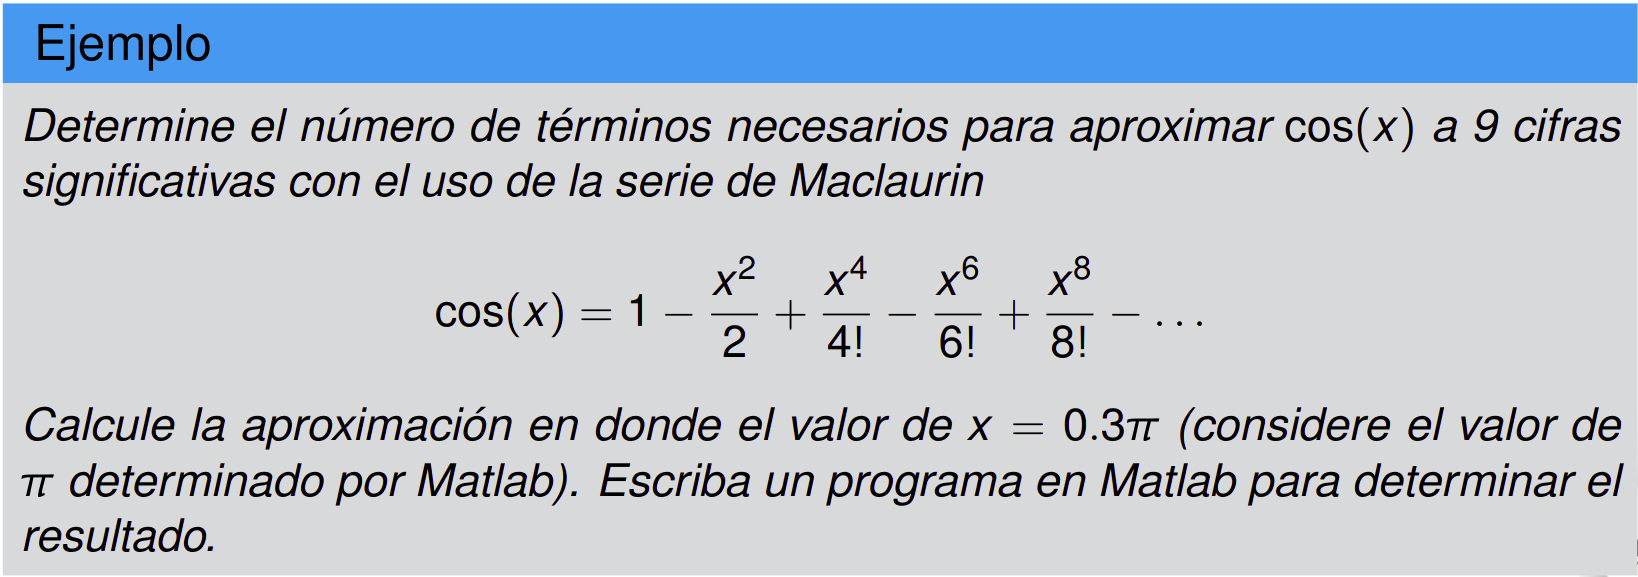

pi % constante de Matlab

ans = 3.1416

x=0.3*pi;
fcos(x,2) % 3 términos

ans = 0.5887

Con deslizador

nTer = 6

nTer = 6

A=cos(x); % valor exacto
Tol=5e-9; % tolerancia de 8 cifras significativas
a=fcos(x,nTer-1);
delta=abs(a-A)/abs(A);
disp(table(nTer,a,delta))

    nTer       a         delta   
    ____    _______    __________

     6      0.58779    1.7361e-09



if delta > Tol*0.1 && delta <=Tol
   fprintf('a aproxima A con 9 cifras significativas empleando %d términos',nTer)
end

a aproxima A con 9 cifras significativas empleando 6 términos

Con bucles

n_ter=NaN; % número de términos
for n=0:6
   a_n=fcos(x,n);
   delta_n=abs(a_n-A)/abs(A);
   disp(table(n,a_n,delta_n))
   if delta_n > Tol*0.1 && delta_n <=Tol
       n_ter=n+1; % número de términos
   end
end

    n    a_n    delta_n
    _    ___    _______

    0     1     0.7013 

    n      a_n      delta_n 
    _    _______    ________

    1    0.55587    0.054301

    n      a_n      delta_n
    _    _______    _______

    2    0.58874    0.00163

    n      a_n       delta_n  
    _    _______    __________

    3    0.58777    2.6011e-05

    n      a_n       delta_n  
    _    _______    __________

    4    0.58779    2.5752e-07

    n      a_n   

n_ter 

n_ter = 6

Por lo tanto, necesito 6 términos (sumandos)

Funciones de usuario

function S=fcos(x,n)
% S=FCOS(x,n) devuelve la exponencial de x usando la fórmula
% S=1-x^2/2+x^4/4!...+(-1)^n * x^(2n)/(2n)!
% 

% % OBS: S considera n+1 términos

S=0;
for k=0:n
    S = S + ((-1)^k)*(x^(2*k))/factorial(2*k);
end

end